% Initialize empty cell arrays to store the data
sitting_data = {};
walking_data = {};
jumping_data = {};
jumping_walking_data = {};

% Loop through the subfolders and load the .mat files
folders = {'sitting', 'walking', 'jumping', 'jumping_walking'};
for i = 1:length(folders)
    folder = folders{i};
    files = dir(fullfile(folder, '*.mat'));
    for j = 1:length(files)
        filename = fullfile(folder, files(j).name);
        data = load(filename);
        switch folder
            case 'sitting'
                sitting_data{j} = data;
            case 'walking'
                walking_data{j} = data;
            case 'jumping'
                jumping_data{j} = data;
            case 'jumping_walking'
                jumping_walking_data{j} = data;
        end
    end
end

walking_data{1} = walking_data{2}

walking_data = 1×10 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


% Calculate the mean of absolute values for each table
sitting_means = []


sitting_means =

     []



walking_means = []


walking_means =

     []



jumping_means = []


jumping_means =

     []



jumping_walking_means = []


jumping_walking_means =

     []




for i = 1:10
    sitting_means = [sitting_means; mean(abs(sitting_data{i}.Acceleration))];
    walking_means = [walking_means; mean(abs(walking_data{i}.Acceleration))];
    jumping_means = [jumping_means; mean(abs(jumping_data{i}.Acceleration))];
    jumping_walking_means = [jumping_walking_means; mean(abs(jumping_walking_data{i}.Acceleration))];
end


sitting_means

sitting_means = 10×3 table
       X          Y         Z   
    _______    _______    ______

    0.76352    0.88737    9.4883
    0.63068    0.53145    9.5625
    0.65807    0.44486    9.5822
    0.72266    0.52483    9.5519
      1.333    0.30959    9.6042
     1.3649    0.27113    9.5927
    0.55711     1.8884    9.1388
    0.25863     1.4233    9.3369
     1.6581     4.0628    7.9655
     1.4127     1.4407    9.2699


walking_means

walking_means = 10×3 table
       X         Y         Z   
    _______    ______    ______

     1.2272    4.1684    8.8701
     1.2272    4.1684    8.8701
    0.78704    4.7494    8.5711
    0.90901    5.0618    8.4335
     1.7572    6.0604    7.5163
     1.3792    5.1287    8.1988
     1.1658    4.0322    8.8858
       1.14    4.8101    8.4766
     1.2079    4.9368    8.4386
     1.0978    3.9841    8.9591


jumping_means

jumping_means = 10×3 table
      X         Y         Z   
    ______    ______    ______

    2.9526    3.1732    7.5685
    2.0811    2.8366    8.1681
    1.5977    2.1913     8.487
    2.5966    2.7258    8.4594
    3.0973    2.9944    8.1783
    4.5816    3.1265    9.2578
    7.4505    4.0701    10.538
    4.5815    2.7062    7.8971
    7.9956    5.4469     10.89
    7.3168    6.8139    8.4956


jumping_walking_means

jumping_walking_means = 10×3 table
      X         Y         Z   
    ______    ______    ______

    10.433    4.0448    9.3096
    15.387    9.7871    13.094
    10.014    4.6932    8.5497
    11.178    4.5095    9.9937
    11.169    4.4264    8.9088
    10.362     4.836    7.1292
    4.2632    3.8609    11.989
    2.5516    4.4967    11.345
    11.465    6.7182    12.343
    7.6623    3.3192    9.2303


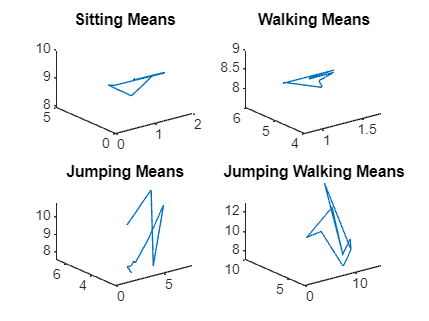

figure;
subplot(2,2,1);
plot3(sitting_means.X, sitting_means.Y, sitting_means.Z);
title('Sitting Means');

subplot(2,2,2);
plot3(walking_means.X, walking_means.Y, walking_means.Z);
title('Walking Means');

subplot(2,2,3);
plot3(jumping_means.X, jumping_means.Y, jumping_means.Z);
title('Jumping Means');

subplot(2,2,4);
plot3(jumping_walking_means.X, jumping_walking_means.Y, jumping_walking_means.Z);
title('Jumping Walking Means');

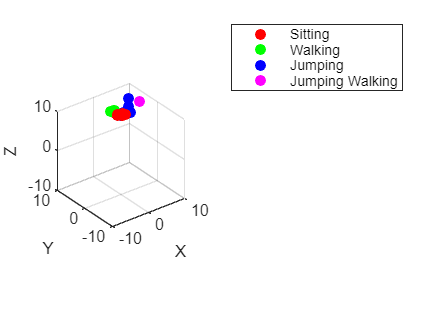

figure;
scatter3(sitting_means.X, sitting_means.Y, sitting_means.Z, 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'r');
hold on;
scatter3(walking_means.X, walking_means.Y, walking_means.Z, 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'g');
scatter3(jumping_means.X, jumping_means.Y, jumping_means.Z, 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'b');
scatter3(jumping_walking_means.X, jumping_walking_means.Y, jumping_walking_means.Z, 'MarkerFaceColor', 'm', 'MarkerEdgeColor', 'm');
xlabel('X');
ylabel('Y');
zlabel('Z');
legend('Sitting', 'Walking', 'Jumping', 'Jumping Walking');
axis equal;
xlim([-10, 10]);
ylim([-10, 10]);
zlim([-10, 10]);

% Assuming your data is already loaded into the following variables:
% sitting_means, walking_means, jumping_means, jumping_walking_means

% Combine the data into a single matrix
data = [sitting_means; walking_means; jumping_means; jumping_walking_means];

% Create labels for each class
numSitting = size(sitting_means, 1);
numWalking = size(walking_means, 1);
numJumping = size(jumping_means, 1);
numJumpingWalking = size(jumping_walking_means, 1);

labels = [repmat({'sitting'}, numSitting, 1); ...
          repmat({'walking'}, numWalking, 1); ...
          repmat({'jumping'}, numJumping, 1); ...
          repmat({'jumping_walking'}, numJumpingWalking, 1)];

% Convert labels to categorical if needed
labels = categorical(labels);

% Split the data into training and testing sets (e.g., 70% training, 30% testing)
cv = cvpartition(labels, 'HoldOut', 0.3);
trainData = data(training(cv), :);
trainLabels = labels(training(cv), :);
testData = data(test(cv), :);
testLabels = labels(test(cv), :);

% Train a classifier (e.g., k-NN with 5 neighbors)
classifier = fitcknn(trainData, trainLabels, 'NumNeighbors', 5);

% Predict labels for the test data
predictedLabels = predict(classifier, testData);

% Calculate accuracy
accuracy = sum(predictedLabels == testLabels) / length(testLabels) * 100;

% Display the accuracy
fprintf('Classification accuracy: %.2f%%\n', accuracy);

Classification accuracy: 83.33%


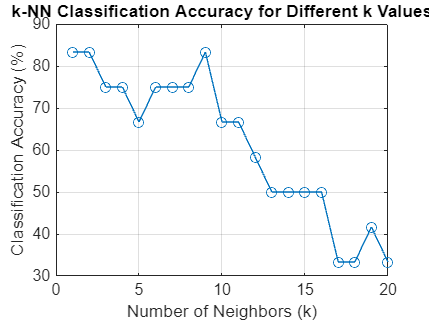

% Assuming your data is already loaded into the following variables:
% sitting_means, walking_means, jumping_means, jumping_walking_means

% Combine the data into a single matrix
data = [sitting_means; walking_means; jumping_means; jumping_walking_means];

% Create labels for each class
numSitting = size(sitting_means, 1);
numWalking = size(walking_means, 1);
numJumping = size(jumping_means, 1);
numJumpingWalking = size(jumping_walking_means, 1);

labels = [repmat({'sitting'}, numSitting, 1); ...
          repmat({'walking'}, numWalking, 1); ...
          repmat({'jumping'}, numJumping, 1); ...
          repmat({'jumping_walking'}, numJumpingWalking, 1)];

% Convert labels to categorical if needed
labels = categorical(labels);

% Split the data into training and testing sets (e.g., 70% training, 30% testing)
cv = cvpartition(labels, 'HoldOut', 0.3);
trainData = data(training(cv), :);
trainLabels = labels(training(cv), :);
testData = data(test(cv), :);
testLabels = labels(test(cv), :);

% Initialize array to store accuracies for different k values
k_values = 1:20; % Range of k values to test
accuracies = zeros(length(k_values), 1);

% Iterate over each k value
for i = 1:length(k_values)
    k = k_values(i);
    
    % Train a k-NN classifier with k neighbors
    classifier = fitcknn(trainData, trainLabels, 'NumNeighbors', k);
    
    % Predict labels for the test data
    predictedLabels = predict(classifier, testData);
    
    % Calculate accuracy
    accuracy = sum(predictedLabels == testLabels) / length(testLabels) * 100;
    accuracies(i) = accuracy;
end

% Plot the accuracies
figure;
plot(k_values, accuracies, '-o');
xlabel('Number of Neighbors (k)');
ylabel('Classification Accuracy (%)');
title('k-NN Classification Accuracy for Different k Values');
grid on;

sample = jumping_walking_data{1}.Acceleration

sample = 476×3 timetable
           Timestamp                X           Y         Z   
    ________________________    _________    _______    ______

    20-Jun-2024 11:48:50.138     -0.99389    0.58209    10.832
    20-Jun-2024 11:48:50.158    -0.050877    0.46388    11.273
    20-Jun-2024 11:48:50.178      0.54408    0.75208    11.486
    20-Jun-2024 11:48:50.198        1.576     1.5661    10.598
    20-Jun-2024 11:48:50.218        2.194     2.3771    8.8259
    20-Jun-2024 11:48:50.238       1.9279     2.2889    9.3721
    20-Jun-2024 11:48:50.258        2.194      1.848    9.0941
    20-Jun-2024 11:48:50.278        2.677        2.1     7.914
    20-Jun-2024 11:48:50.298       2.1841     2.7719   

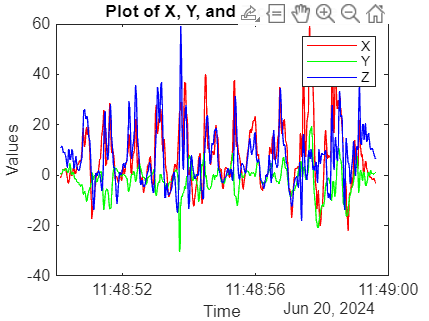

time = sample.Timestamp;
x = sample.X;
y = sample.Y;
z = sample.Z;
figure;
plot(time, x, 'Color', [1 0 0]);  % Red
hold on;
plot(time, y, 'Color', [0 1 0]);  % Green
plot(time, z, 'Color', [0 0 1]);  % Blue
hold off;
xlabel('Time');
ylabel('Values');
title('Plot of X, Y, and Z over Time');
legend('X', 'Y', 'Z');